# DSZOB, cvičenie 4.

## **Zadanie:**

## **Úloha 1 - **Analýza signálu

**Nasnímajte signál zvuku ladičky. **

Vizualizujte nasnímaný signál v priestorovej doméne. Na základe vizualizácie vyberte vhodný úsek, vypočítajte a vizualizujte preň Fourierovu transformáciu:

- Cez funkciu **fft** na malej vzorke dát (napr. 512)

- Prepočítajte index spektrálneho koeficienta na frekvenciu pre najväčsiu hodnotu v grafe

- Cez funkciu **spectrogram**

- Zistite dominantnú frekvenciu daného signálu a vyznačte ju v grafe.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

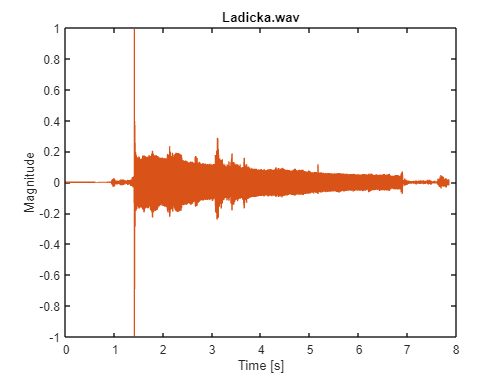

clear
fork = audioread("Asignments\Assignment_3\ladicka.wav");
fork_info = audioinfo("Asignments\Assignment_3\ladicka.wav");
fs = fork_info.SampleRate;
time_axis = 0:1/fs:fork_info.Duration;
time_axis(end) = [];    % Fix for rounding issue
plot(time_axis, fork);
title("Ladicka.wav")
xlabel("Time [s]");
ylabel("Magnitude")

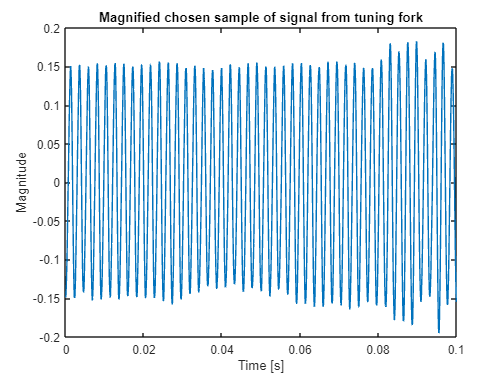

fork_sample = fork(fs*2: fs*4, 1);
time_axis_sample = 0:1/fs:2;
plot(time_axis_sample, fork_sample); % between first and second second
title("Magnified chosen sample of signal from tuning fork")
xlabel("Time [s]");
ylabel("Magnitude");
xlim([0,0.1])

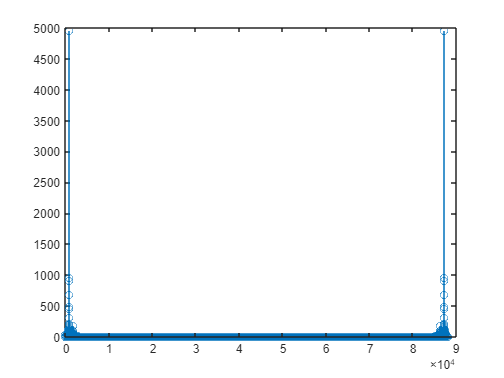

fork_dft = fft(fork_sample);
stem(abs(fork_dft))

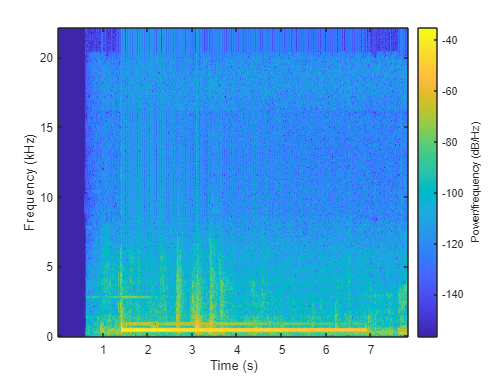

spectrogram(fork(:,1), 512, 256 , 512, fs, "yaxis")

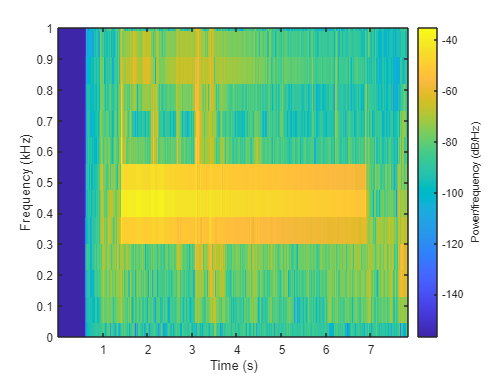

spectrogram(fork(:,1), 512, 256 , 512, fs, "yaxis")
ylim([0, 1])

**Answer: **Dominantná frekvencia je 0.3-0.55 kHz

## **Úloha 2 - Zero Padding v spektrálnej doméne**

Vygenerujte si náhodne zložený signál s dĺžkou 1 sekunda a s voľne zvolenou malou vzorkovacou frekvenciou. Zvolte si parametre signálu tak, aby najväčšia frekvencia generovaného signálu neprekročila 16Hz a vzorkovacia frekvencia pod 64Hz. Dbajte pri tom na to, aby bol splnený Nyquistov teorém. 

Vykonajte zero padding signálu v spektrálnej doméne tak, že doplníte nulami spektrum od jeho stredu (stred symetrie musí ostať zachovaný). Doplnenie vykonajte na velkosť vzorky 1024. Následne vykonajte spätnú transformáciu do časovej domény. Pôvodný signál, ako aj novo vytvorený spoločne vizualizujte v jednom grafe, kde x-os bude reprezentovať čas v rozsahu 1 sek.

Zodpovedajte nasledovné otázky:

- Akú výhodu nam priniesol zero padding v spektre?

- Vie nám zero padding v spektre pomôcť v prípade, ak bol porušený Nyquistov teorém v pôvodnom signále? (áno/nie)

## Pomôcky:

- complex()

- zeros()

- ifft()

## Poznámka:

- Spektrum signálu obsahuje magnitúdovú aj fázovú zložku. Pri dopĺňaní spektra nulami teda pracujeme s komplexnými číslami (0 + 0*i)

- Po spätnom prepočte inverznej transformacie prenásobte výsledný signál konštantou 1024/Fs pre normalizáciu hodnôt na veľkosť okienka

## **Riešenie:**

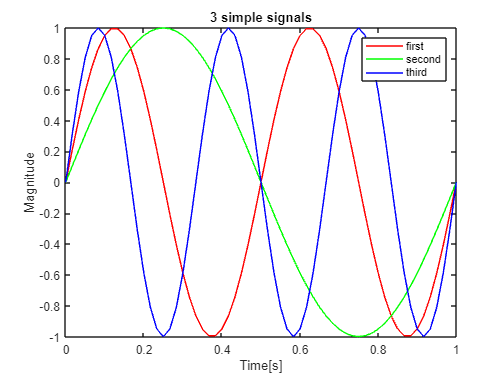


frequency = 60;
t = 1;
time_axis = 0:1/frequency:t;

first = 2;
second = 1;
third = 3;

frequency_1 = first * 2 * pi;
frequency_2 = second * 2 * pi;
frequency_3 = third * 2 * pi;
sig_1 = sin(time_axis * frequency_1);
sig_2 = sin(time_axis * frequency_2); 
sig_3 = sin(time_axis * frequency_3); 

plot(time_axis, sig_1, "red");  hold on
plot(time_axis, sig_2, "green");
plot(time_axis, sig_3, "blue");
xlabel("Time[s]");
ylabel("Magnitude");
title("3 simple signals");
legend("first", "second", "third")
hold off

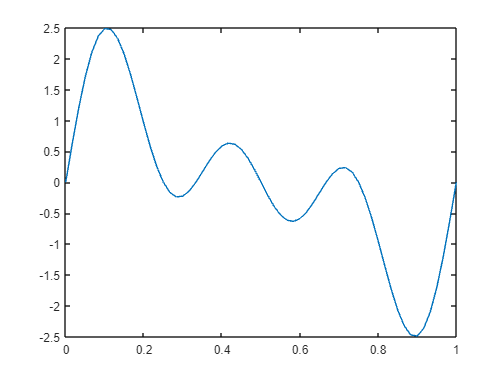

composite = sig_1 + sig_2 + sig_3;
plot(time_axis, composite)

length(time_axis)

ans = 61

complex(time_axis)

ans =    0.0000 + 0.0000i   0.0167 + 0.0000i   0.0333 + 0.0000i   0.0500 + 0.0000i   0.0667 + 0.0000i   0.0833 + 0.0000i   0.1000 + 0.0000i   0.1167 + 0.0000i   0.1333 + 0.0000i   0.1500 + 0.0000i   0.1667 + 0.0000i   0.1833 + 0.0000i   0.2000 + 0.0000i   0.2167 + 0.0000i   0.2333 + 0.0000i   0.2500 + 0.0000i   0.2667 + 0.0000i   0.2833 + 0.0000i   0.3000 + 0.0000i   0.3167 + 0.0000i   0.3333 + 0.0000i   0.3500 + 0.0000i   0.3667 + 0.0000i   0.3833 + 0.0000i   0.4000 + 0.0000i   0.4167 + 0.0000i   0.4333 + 0.0000i   0.4500 + 0.0000i   0.4667 + 0.0000i   0.4833 + 0.0000i   0.5000 + 0.0000i   0.5167 + 0.0000i   0.5333 + 0.0000i   0.5500 + 0.0000i   0.5667 + 0.0000i   0.5833 + 0.0000i   0.6000 + 0.0000i   0.6167 + 0.0000i   0.6333 + 0.0000i   0.6500 + 0.0000i   0.6667 + 0.0000i   0.6833 + 0.0000i   0.7000 + 0.0000i   0.7167 + 0.0000i   0.7333 + 0.0000i   0.7500 + 0.0000i   0.7667 + 0.0000i   0.7833 + 0.0000i   0.8000 + 0.0000i   0.8167 + 0.0000i


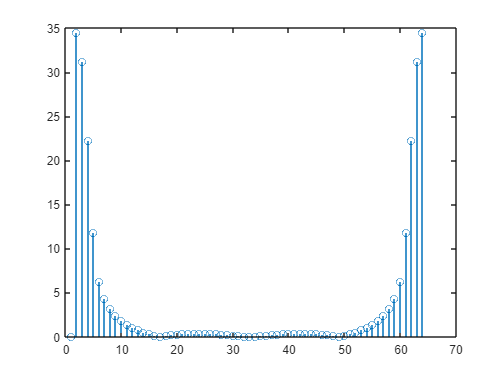

composite_dft = fft(composite);
stem(abs(composite_dft))

length(composite_dft)

ans = 64

zeros(937)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 